# Online Directional Convolution

% clear
close all

## Grid

grid = OctoGrid(2,2,2,100);

% add column
% grid.addBox(1.25,0.9,0,0.2,0.2,1.5)

% add wall
grid.addBox(0.2,0.8,0,1.6,0.1,1.5)

## Generate goal points

% trajectory generation points (xyz position, xyz angles)
control_points = [1.088 1 0.926 0 0 0;
                  1.4 1.2 0.5 0 0 0]; 

## Robot Base position

% robot base transformation (move to x - 1m, y - 1m)
Tbase = eye(4);
Tbase(1:2,4) = [1 1]';

% joints
q = zeros(7,1);

## Calculate field

% Attractive
[grid_attractive] = attractive_field_3D(grid.grid, control_points(2,1:3), grid.resolution);

% Repulsive
kernel_size = 50; % how far should obstacles exert effect
sigma = 25 ; % how quickly should effect exerted by obstacles fall

% [grid_repulsive] = convolution_offline_3D(grid.grid,kernel_size,sigma);

% Total
Ka = 10; % attractive field coefficient
Kr = -5; % repulsive field coefficient

% total field is a weighted sum of both
% grid_total_field = Ka * grid_attractive + Kr * grid_repulsive;

## Path planning

% [joints_positions, EE_positions, goal_distances, q_velocities] = kinematics_trajectory(control_points(2,1:3), Tbase, q);
[joints_positions, EE_positions, goal_distances, q_velocities, ee_velocities, values_secondary] = ObstacleGrid_RTConvolution_OnePoint(grid, grid_attractive, control_points(2,1:3), Tbase, q,'avoid_task', true, 'mid_joints', true);

## Show results

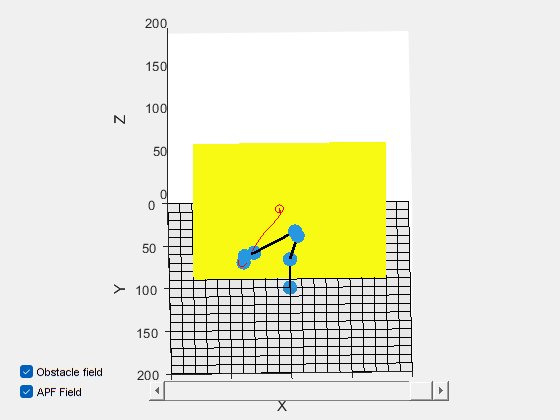

Index in position 2 exceeds array bounds. Index must not exceed 1.

Error in showMovementPanda (line 107)
        APF_handles(i) = quiver3(values_APF(j).xyz(i,1)*grid.resolution, values_APF(j).xyz(i,2)*grid.resolution, values_APF(j).xyz(i,3)*grid.resolution, values_APF(j).grad(i,1) * arrow_length, values_APF(j).grad(i,2) * arrow_length, values_APF(j).grad(i,3) * arrow_length, arrow_length/2, 'LineWidth', 2, 'MaxHeadSize', 1);

f1 = figure;
showMovementPanda(grid, [], control_points, joints_positions, EE_positions, values_secondary, Tbase)